# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.7 知乎提问

#### 2.7.2 二维的曲线图怎么转化为三维的曲面图?

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

原问题：[https://www.zhihu.com/question/525678201/answer/2420769077](https://www.zhihu.com/question/525678201/answer/2420769077)

# 有个MATLAB的问题想问下知友:就是这种二维的曲线图怎么转化为三维的曲面图呀 ?

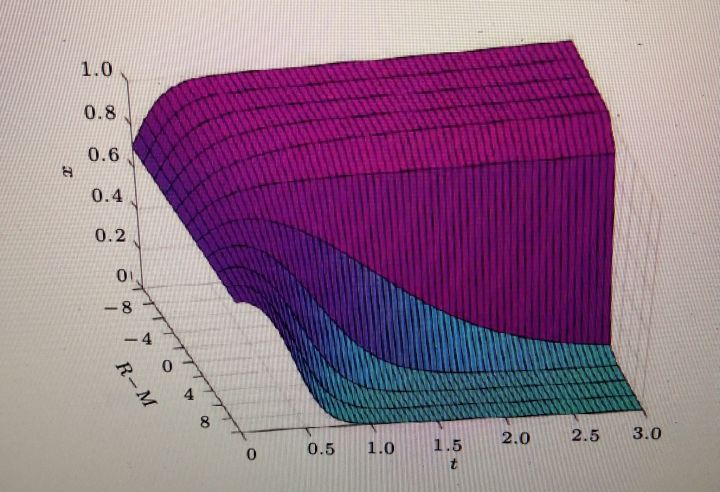

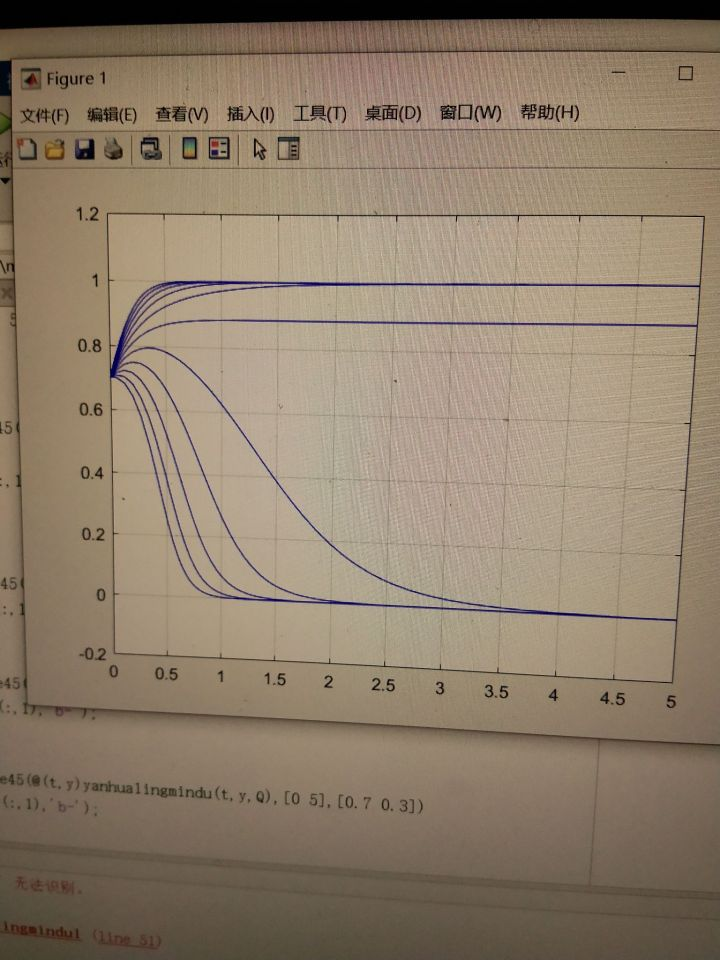

图一是别人论文里的；图二是我自己画的，不会转化了

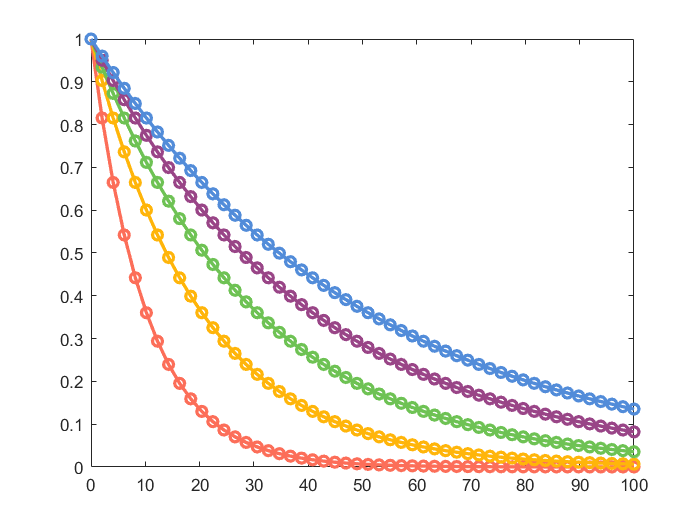

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors();
% 创建一个colormap
map = GenColormap(all_themes{1});
x = linspace(0, 100, 50);
y1 = exp(-x/10);
y2 = exp(-x/20);
y3 = exp(-x/30);
y4 = exp(-x/40);
y5 = exp(-x/50);
figure;
plot(x, y1, 'o-', 'LineWidth', 2);
hold on
plot(x, y2, 'o-', 'LineWidth', 2);
plot(x, y3, 'o-', 'LineWidth', 2);
plot(x, y4, 'o-', 'LineWidth', 2);
plot(x, y5, 'o-', 'LineWidth', 2);
hold off
set(gca, 'colororder', all_themes{1});

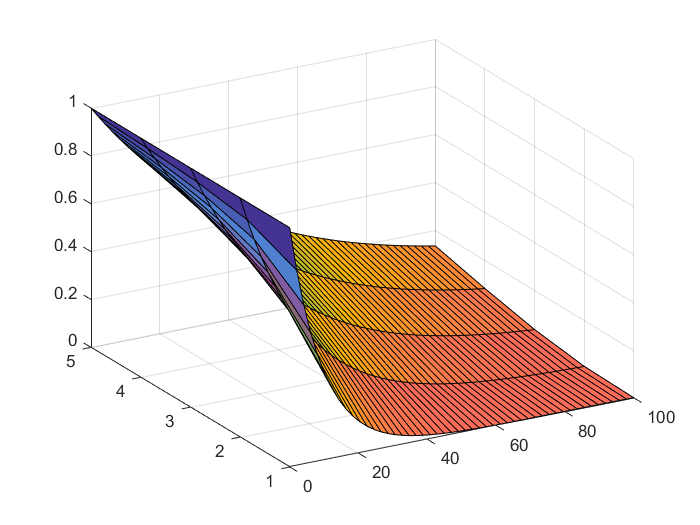

figure;
surf(x, 1:5, [y1; y2; y3; y4; y5]);
colormap(map);
view(-30, 30);